# Problema 3

Tercer examen parcial.

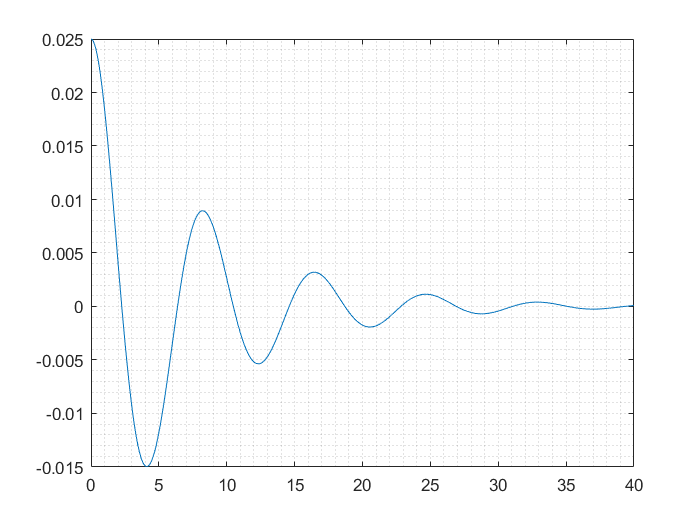

h = 0.01;
m1 = 0.05; m2 = m1;
k1 = 0.01; k2 = k1; k3 = k2;
b = 0.0125;

xv0 = [0.025;-0.025; 0; 0];

M = [0, 0, 1, 0; 0, 0, 0, 1; -(k1+k2)/m1, k2/m1, -b/m1, 0; k2/m2, -(k2+k3)/m2, 0, -b/m2];

f = @(t, xv) M*xv;

[t,y] = ivps(f,0,40,xv0,h, 5);
plot(t,y(1,:));
grid minor

lambda = eig(M)

lambda =   -0.1250 + 0.7644i
  -0.1250 - 0.7644i
  -0.1250 + 0.4294i
  -0.1250 - 0.4294i


w = imag(lambda(:,1))

w =     0.7644
   -0.7644
    0.4294
   -0.4294


f = w/(2*pi)

f =     0.1217
   -0.1217
    0.0683
   -0.0683


T = 1./f

T =     8.2193
   -8.2193
   14.6328
  -14.6328
